# Compute Binomial Coefficients Exactly

This example shows how to get precise values for binomial coefficients and find probabilities in coin-tossing experiments using the Symbolic Math Toolbox.

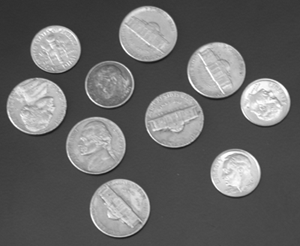

Define the symbolic function, `P(n,k)`, that computes the probability for the heads to come up exactly `k` times out of `n` tosses.

syms P(n,k)
P(n,k) = nchoosek(n,k)/2^n

Suppose, you toss a coin 2000 times. The probability that heads comes up in half of the tosses is `P(n, n/2)`, where `n = 2000`. The result is a rational expression with large numbers in both the numerator and denominator. Symbolic Math Toolbox returns the exact result.

n = 2000;
central = P(n, n/2)

Approximate this rational number with 10-digit accuracy using `digits` and `vpa`.

previous_digits = digits(10);
vpa(central)

Compute the probability that the number of "heads" differs from the expected value by no more than two standard deviations.

sigma = sqrt(n/4);
withinTwoSigma = symsum(P(n, k), k, ceil(n/2 - 2*sigma), floor(n/2 + 2*sigma))

Approximate the result with a floating-point number.

vpa(withinTwoSigma)

Compare this result with the following two estimates derived from the cumulative distribution function (cdf) of the normal distribution. It turns out that taking the midpoint between the first integer outside and the first integer inside the two-sigma interval gives a more precise result than using the two-sigma interval itself.

syms cdf(x)
cdf(x) = 1/2 * (1 + erf((x - n/2)/sqrt(sym(n/2))))
estimate1 = vpa(cdf(n/2 + 2*sigma) - cdf(n/2 - 2*sigma))
estimate2 = vpa(cdf(floor(n/2 + 2*sigma) + 1/2) - ...
                cdf(ceil(n/2 - 2*sigma) - 1/2))
error1 = vpa(estimate1 - withinTwoSigma)
error2 = vpa(estimate2 - withinTwoSigma)

Restore the default precision for floating-point computations.

digits(previous_digits);

Plot this distribution for k within the $2\sigma$-interval. The plot is a Gaussian curve.

k = n/2 + (-2*sigma:2*sigma);
plot(k, P(n,k), '-+');
title('2000 coin tosses');
xlabel('Number of heads');
ylabel('Probability');

*Copyright 2014-2016 The MathWorks, Inc.*